# Lattice Filter :

## (a) Lattice Prediction

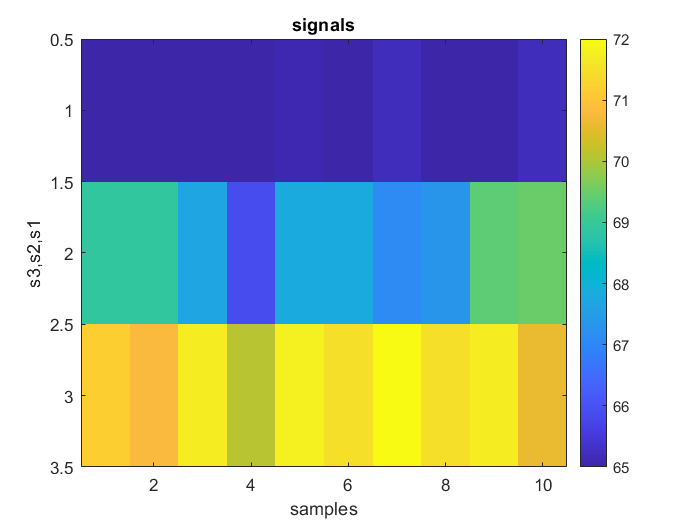

clflag =1;cfg;
% plotting original signals
%
image([s1(1:10),s2(1:10),s3(1:10)]', 'CDataMapping','scaled');colorbar ;

title signals;xlabel samples; ylabel 's3,s2,s1'

% autocorrolation calculation for randomaly chosen signals
%
[rs1, lag] = xcorr(s1, 'biased');rs1(lag<0) =[];

% implementing levinson-durbin to evaluate PARCOR ...
%----------------------------
rss  = rs1(2:pmax+1)';              % 
A      = zeros(pmax);               % A coeff matrix
k      = zeros(1, pmax);            % reflection coeff
J      = zeros(1, pmax);            % error in each order
%----------------------------
% INITILIZATION
%----------------------------
k(1)   = rss(1)/rs1(1);             % k(1) = r(1)/r(0)
A(1,1) = k(1);                      % a(1,1) = A(1,1) = k(1)
J(1) = (1 - k(1)^2) * rs1(1);                      % J_p = r_s(0)
%----------------------------
for i=2:pmax
    
    PsiBT = flip(rss(1:i-1));

    k(i) = ( rss(i) - ( PsiBT * A(1:i-1, i-1) ) )/(J(i-1));
    
    A(1:i-1,i) = A(1:i-1,i-1) - k(i)*flip(A(1:i-1,i-1));
    A(i, i) =k(i);

    J(i) = (1 - k(i)^2) * J(i-1);
end

As1 =A; Js1 =J; ks1 =k;

- Does the same prediction order appear suitable for all sensors? yes it does p =20 is enough

- What do the PARCOR coefficients reveal about signal predictability? if "k" decay rapidly model can be pridicted by less memory.

Using lattice structure :

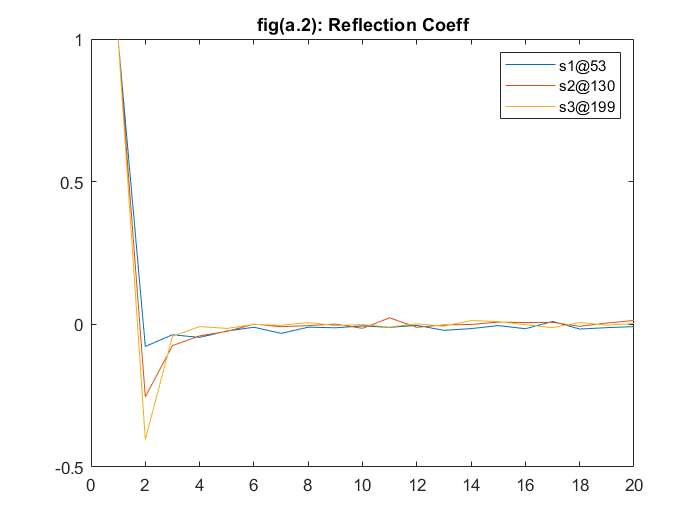

[rs2, lag] = xcorr(s2, 'biased');rs2(lag<0) =[];
[rs3, lag] = xcorr(s3, 'biased');rs3(lag<0) =[];

[As2, Js2, ks2] =levinson_durbin(rs2, pmax);
[As3, Js3, ks3] =levinson_durbin(rs3, pmax);
n=1:20;
figure();
plot(n, ks1, n, ks2, n, ks3);title('fig(a.2): Reflection Coeff')
legend s1@53 s2@130 s3@199 

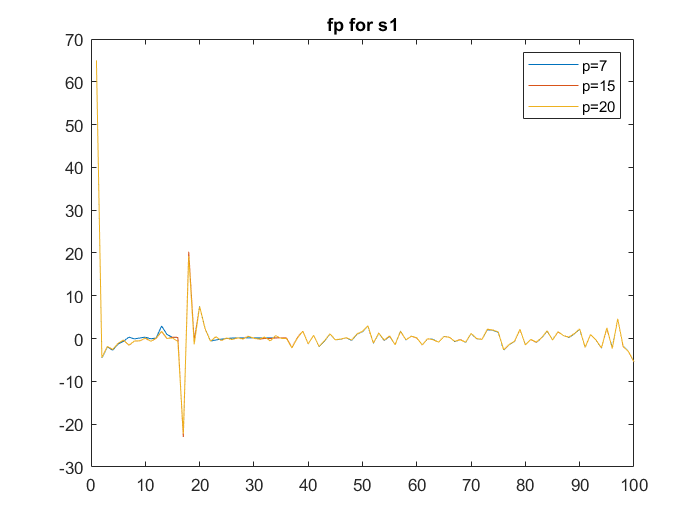


f0 =s1;
b0 =s1;
[F, ~] =latticechain(f0, b0, ks1);

figure();
plot(F(7, 1:100));hold on;
plot(F(15,1:100));
plot(F(20,1:100));hold off;title 'fp for s1';
legend p=7 p=15 p=20;

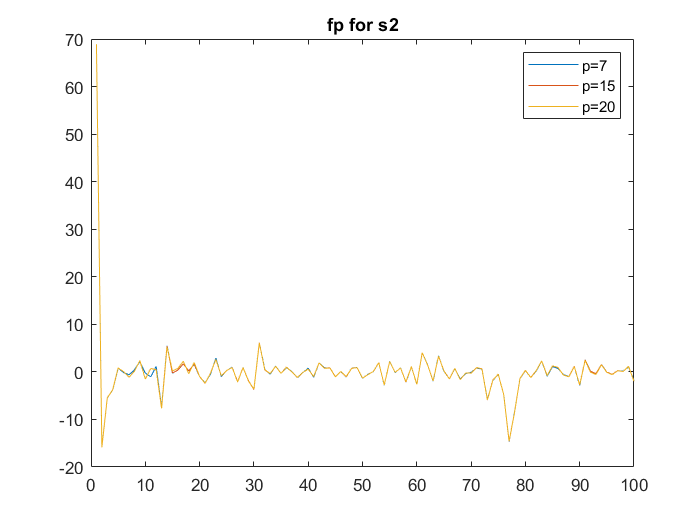

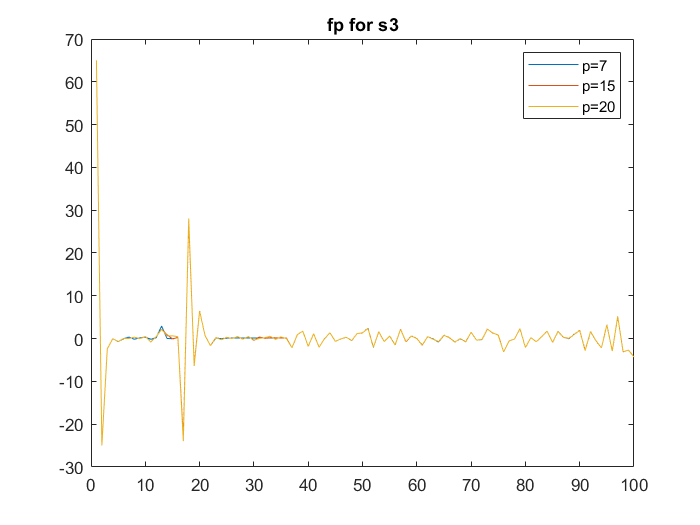

fps1 = F;

a_3

- Based on Forward error in each signal p=7 seems enough to model signal.

## (b) Accident Detection Using the Lattice Predictor

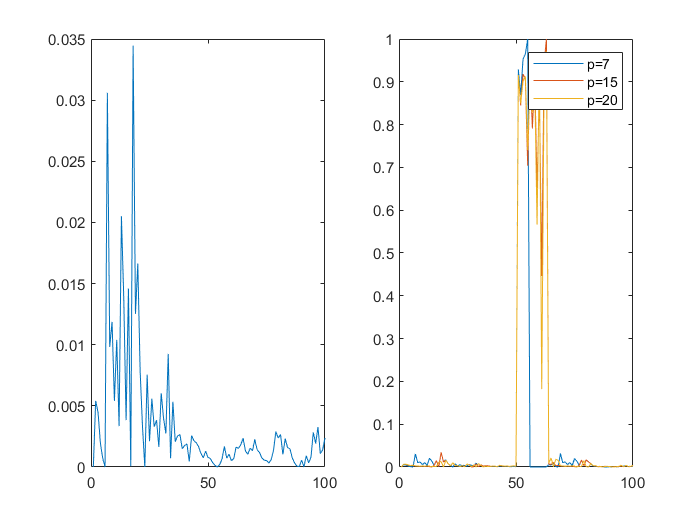

cfg
clflag =1;
s1(50:50+12) = 0;
f0 =s1;
b0 =s1;

[F, B] = latticechain(f0, b0, ks1);
fps1 = normalize(fps1, 'range');
F    = normalize(F   , 'range');

figure();
subplot(1,2,1);
plot(fps1(7, 1:100));
subplot(1,2,2);
plot(F(7, 1:100));hold on;
plot(F(15, 1:100));

plot(F(20, 1:100));hold off;
legend p=7 p=15 p=20

- Forward error increase dramaticly during accident. about 100%.

- It seems like higher orders of yule-wlaker (p > 7) are more sensitive to accidents!

# Adaptive Filter :

## (c) Adaptive Wiener Prediction

With 'Rs1's eigen values order being in x1e4, |1 - $\mu
$.$\lambda_i
$ | < 1, then $\mu
$ must be in 1e-5 order. this pervents divergence.

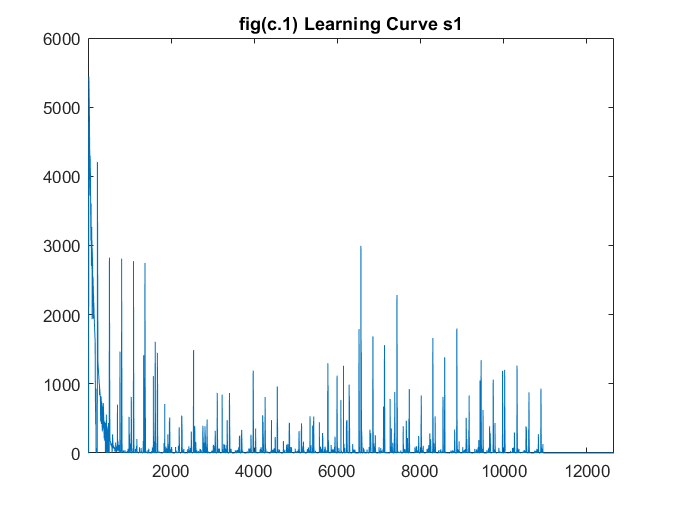

clflag =1;cfg;
%--------------------------
p =15;                                  % Order (taps and weights)
train_data =s1(1:11000);                % training data
tests_data = ...
    [zeros(11000,1);s1(11001:end)];     % test data
w = zeros(p,1);                         % w initial
mu =.0005e-4;                               % learning rate
%--------------------------
LearnCurve =zeros(numel(s1), 1);
PredictSig =zeros(numel(s1), 1);
TestingErr =zeros(numel(s1), 1);

% LMS method ...
for n =1:numel(s1)-p
    termination = e^2 < 1;
    test_cond = n <=numel(train_data)-p;
    % Training-------------------
    if (test_cond)
        x =flip(train_data(n:n+p-1));
        d =x(1);

        y =w' * x;
        e =d - y;

        w = w + mu * e * x;

        LearnCurve(n+p) =e.^2;
        PredictSig(n+p) =y;
    % Testing---------------------
    else
        x =flip(tests_data(n:n+p-1));

        y =w' * x;
        e =d - y;

        TestingErr(n+p) =e;
        PredictSig(n+p) =y;
    end
end
w1 =w;
% Plotting-----------------------------------------------------------------
plot(LearnCurve);title('fig(c.1) Learning Curve s1');xlim([1,n]);

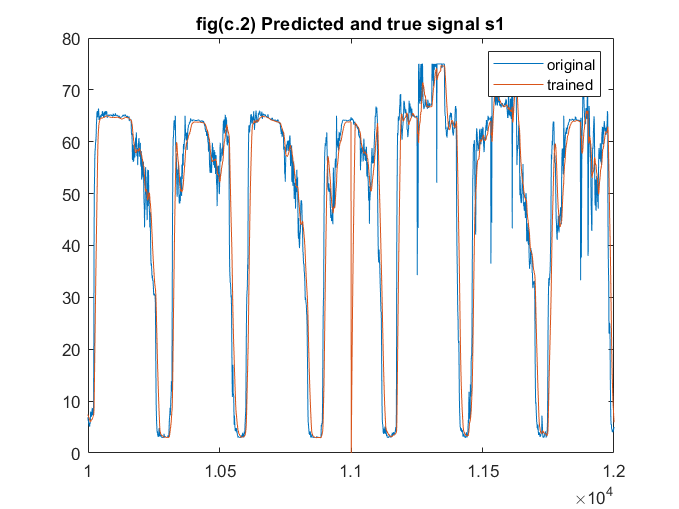

plot(1:n, s1(1:n), 1:n, PredictSig(1:n));
title('fig(c.2) Predicted and true signal s1')
xlim([10000,12000]);legend('original', 'trained');

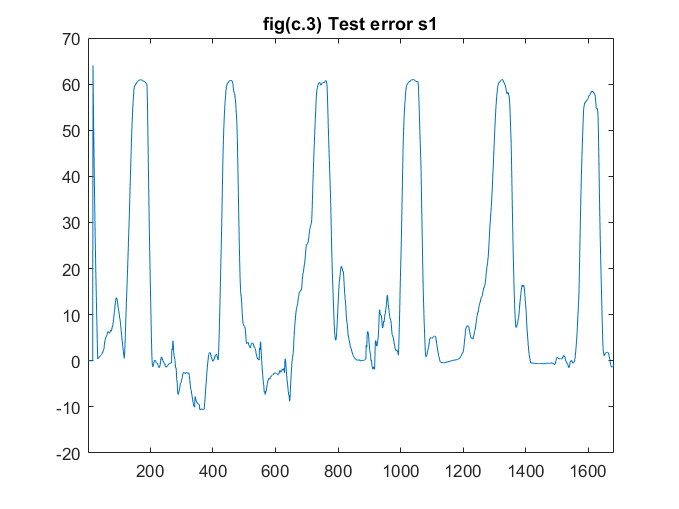

plot(TestingErr(10985:end));xlim([1, 1682]);
title('fig(c.3) Test error s1')

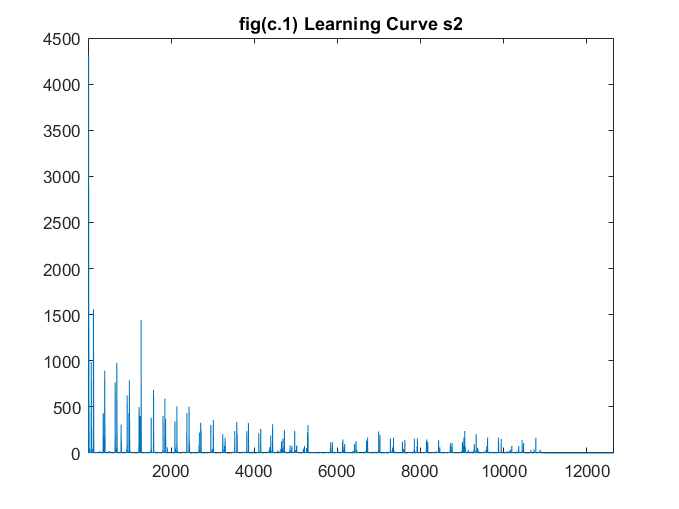

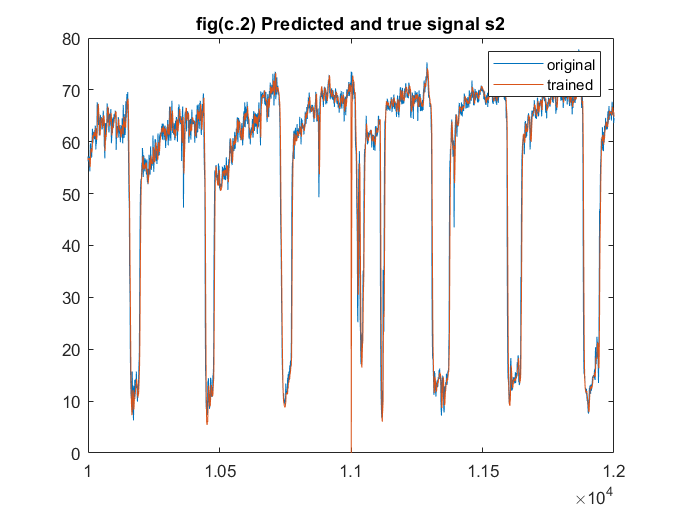

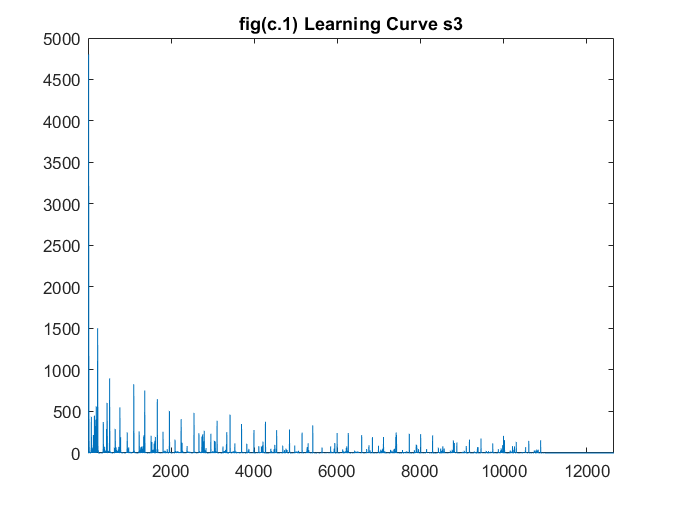

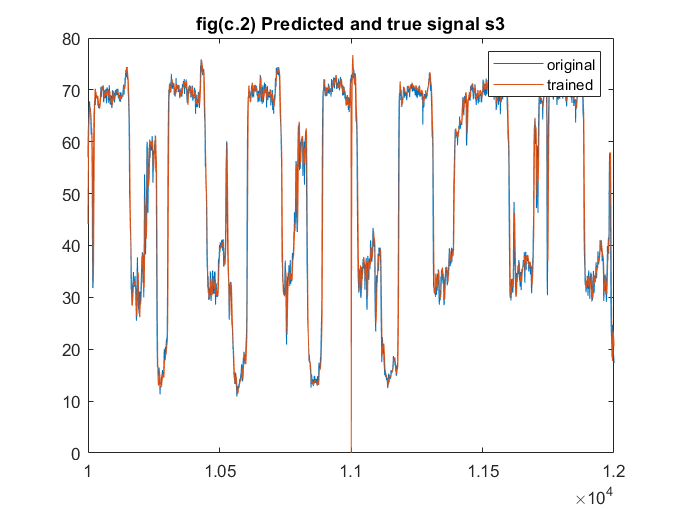

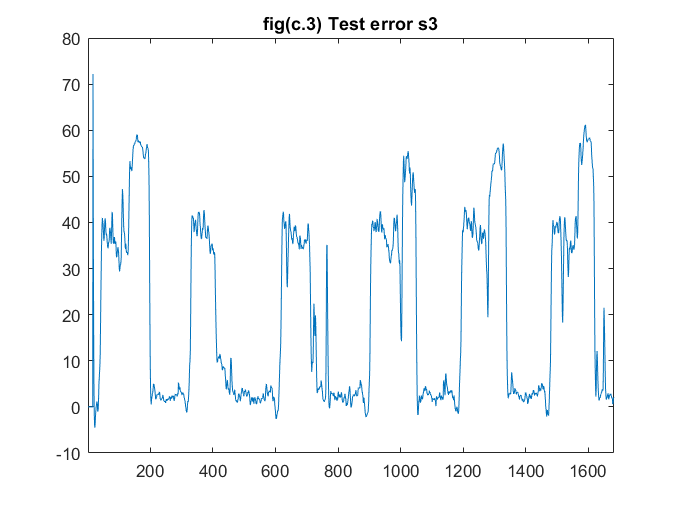


c_1

- According to Learning Curve s1 converges after 1000 iteration s2 -> 150 iter, s3 -> 25 iter

- lattice prediction is a fixed filter while Adaptive filter can changes its weights.

The best approach is to use FIR lattice-ladder filter and find $W =L^{\dagger}C$ with adaptive methods.

disp([w1,w2,w3]);

    0.1007    0.4211    0.4398
    0.0943    0.2851    0.3043
    0.0880    0.1760    0.1825
    0.0819    0.1002    0.0933
    0.0764    0.0488    0.0357
    0.0712    0.0166    0.0021
    0.0665   -0.0006   -0.0143
    0.0622   -0.0093   -0.0201
    0.0584   -0.0120   -0.0193
    0.0550   -0.0109   -0.0155
    0.0521   -0.0100   -0.0101
    0.0497   -0.0061   -0.0047
    0.0478   -0.0023    0.0023
    0.0462    0.0007    0.0099
    0.0450    0.0045    0.0203



## (d) Accident Detection Using Adaptive Filtering

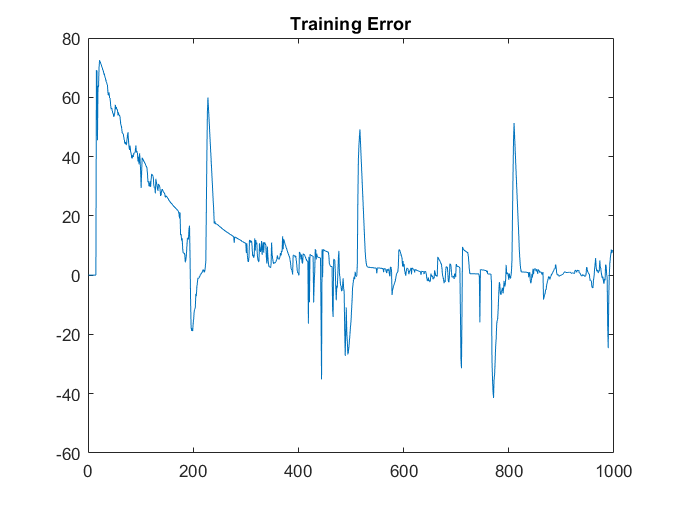

s_acc = s1; s_acc(11100:11100+12) =0;
mu =.001e-4;p =15;n =1;
w  =zeros(p,1);Err =zeros(numel(s_acc), 1);
train =s1(1:11000);
termination =true;
% Training --------------------(LMS)
while (termination)
    x =flip(train(n:n+p-1));d =x(1);

    y =w' * x;
    e =d - y;
    w =w + mu * e * x;
    
    Err(n+p) =e;
    termination = (e^2 >.00001);
    n = n+1;
end
Err(n:end) =[];
TErr =zeros(numel(s_acc), 1);
x_pre =zeros(numel(s_acc), 1);
for n =1:numel(s_acc)-p
    x =flip(s_acc(n:n+p-1));
    d =x(1);

    y =w' * x;
    e =d - y;
    
    TErr(n)  =e;
    x_pre(n) =y;
end

plot(Err);
title('Training Error');

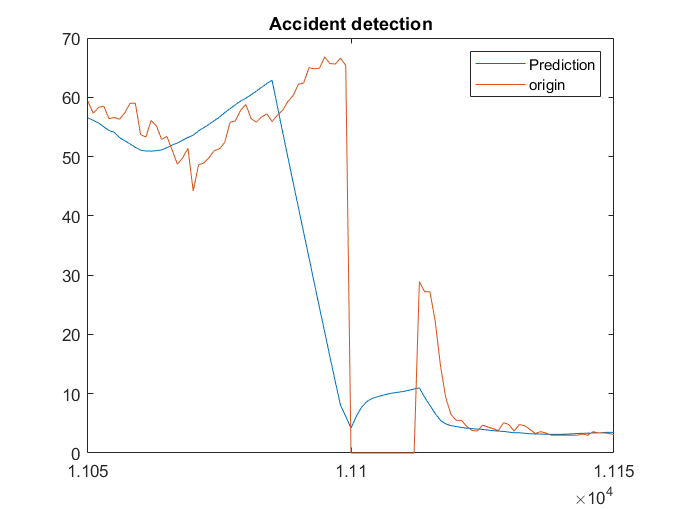

plot(1:n+p, x_pre, 1:n+p, s_acc);
title('Accident detection');xlim([11050, 11150]);
legend('Prediction', 'origin');

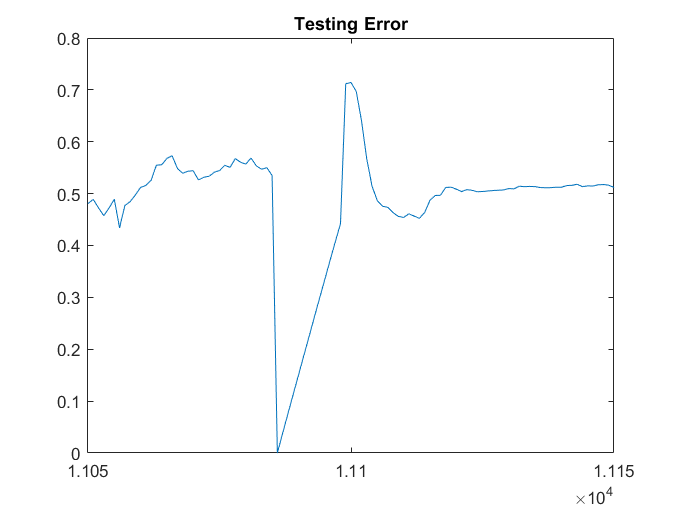

plot(1:n+p, normalize(TErr, 'range'));xlim([11050, 11150]);
title('Testing Error');

- Is the adaptive predictor able to identify the accident? yes figures show that...

- Adaptive is less sensetive than Lattice prediction

# Graph Signal Processing:

## (e) Graph Signal Processing

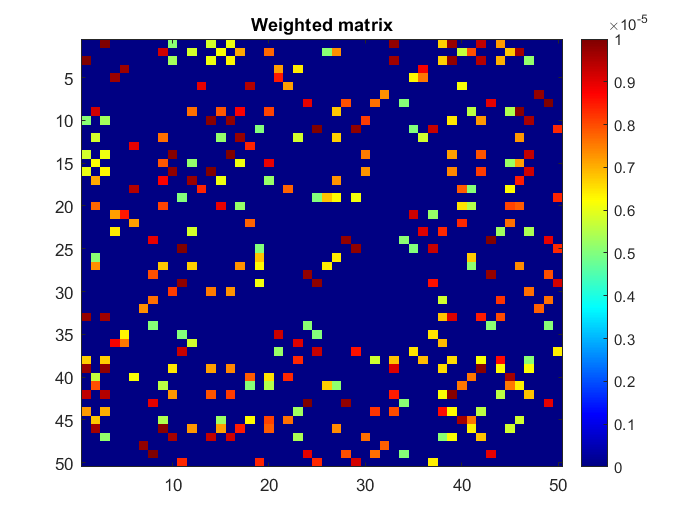

clflag =2;cfg;

distn = (distance.^2)/var(distance(:));

% Constructing Weight matrix
W = exp(-distn)/1e5;
thr =.5/1e5;
W(W <thr) =0;
W(1:51:end) =0;

% Relative Position matrix (Multidimensional scaling)
% for finding xycoords ...
C =eye(50) - ones(50)/50;
B =-.5*C*(distn)*C;
[U, Lambs] =eig(B);
[Lambs, idx] = sort(diag(Lambs), 'descend');
U =U(:,idx);
xycoords =U(:,1:2) * diag(Lambs(1:2));


% Laplacian matrix
Dw =diag(sum(W));
Lw =Dw - W;

[U, Lambs] =eig(Lw);
% [Lambs, idx] =sort(diag(Lambs));
% U =U(:,idx);
% Lamsbs =sqrt(Lambs);

% figures:
figure
image(W, 'CDataMapping','scaled');
colorbar;title('Weighted matrix');colormap('jet');

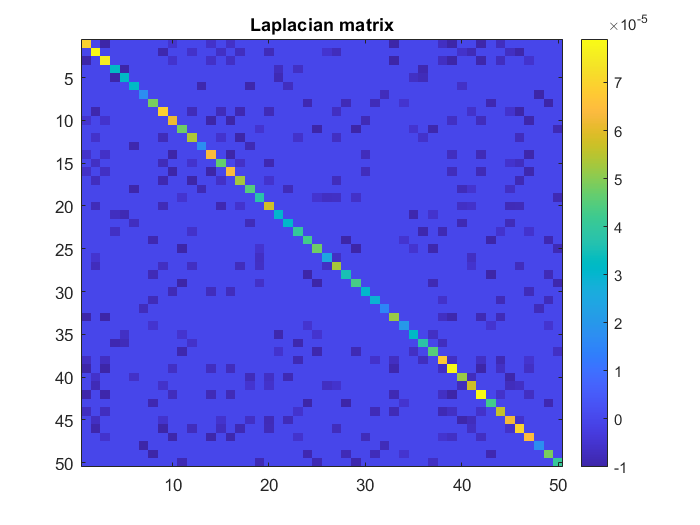

figure
image(Lw, 'CDataMapping','scaled');
colorbar;title('Laplacian matrix');

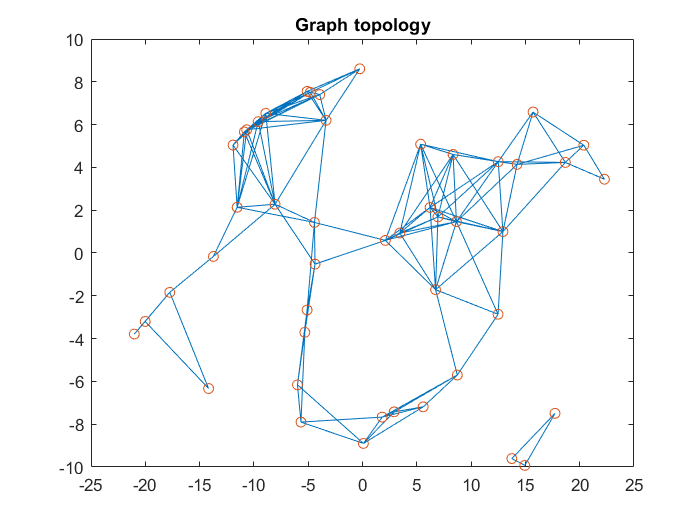

figure
gplot(W, xycoords);hold on;
scatter(xycoords(:,1), xycoords(:,2));hold off;
title('Graph topology');

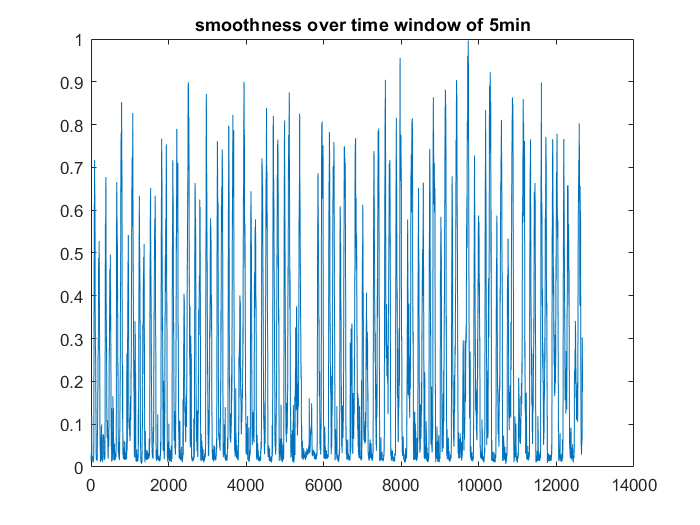


% Averaging Signals---------------------------
L1 = zeros(numel(X)/50, 1);

for k=1:numel(X)/50
    x =X(k,:);
    L1(k) =x * Lw * x';
end
X1 = x;
plot(L1);title('smoothness over time window of 5min');

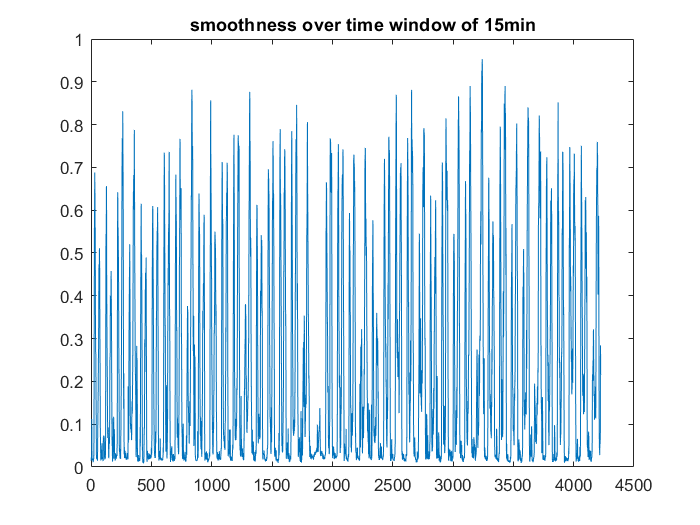

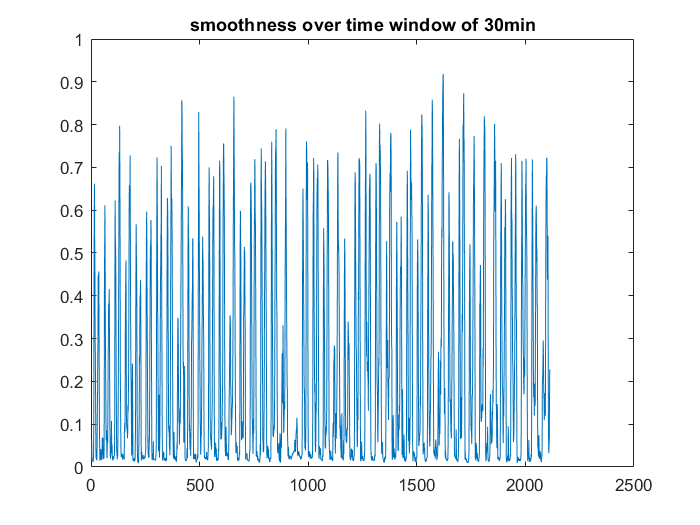

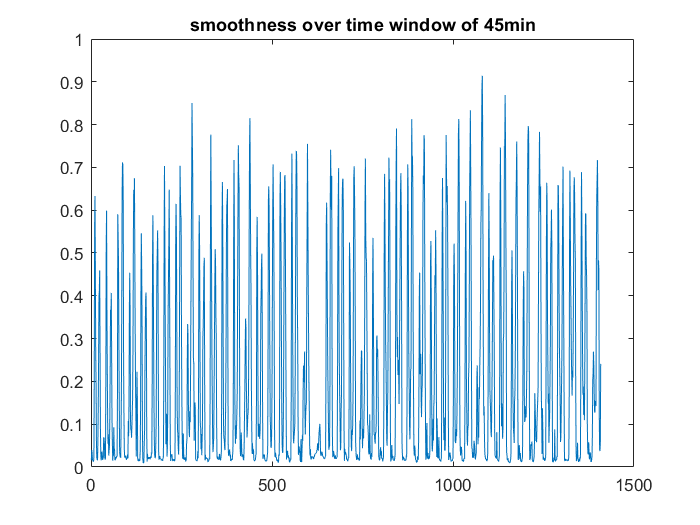

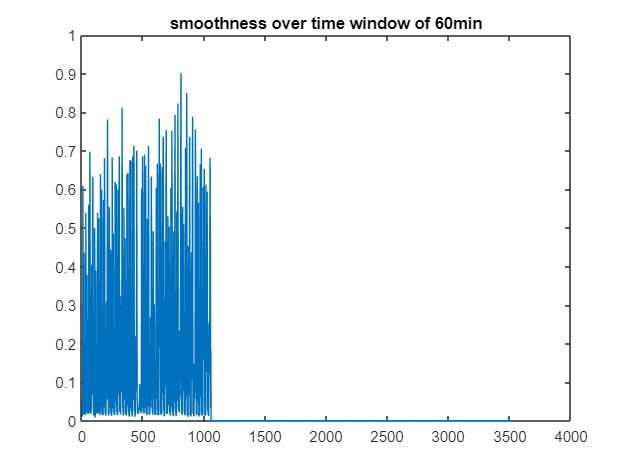


e_3

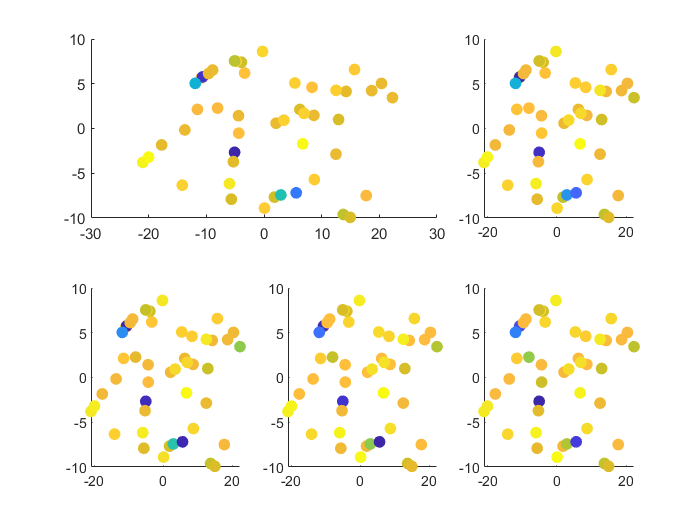


xn =xycoords(:,1);yn =xycoords(:,2);
subplot(2,3,[1,2])
scatter(xn,yn,50,X1,'filled');
subplot(2,3,3)
scatter(xn,yn,50,X3,'filled');
subplot(2,3,4)
scatter(xn,yn,50,X6,'filled');
subplot(2,3,5)
scatter(xn,yn,50,X9,'filled');
subplot(2,3,6)
scatter(xn,yn,50,X12,'filled');

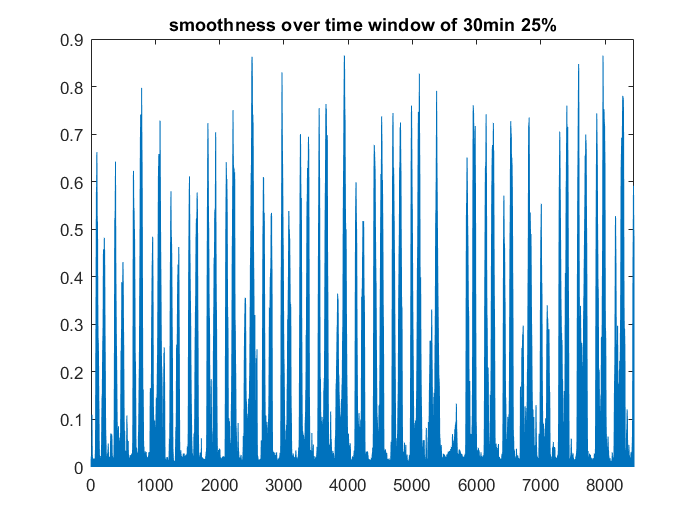

clearvars -except X Lw W SpeedMat WeightMat 
L6_25 = zeros(numel(X)/25/3,1);

for k=1:2:numel(X)/25/3
    x =mean(X(k:k+5, :));
    L6_25(k) =x * Lw * x';
end
X6_25 =x;figure
plot(L6_25);title('smoothness over time window of 30min 25%');xlim([0,numel(L6_25)]);

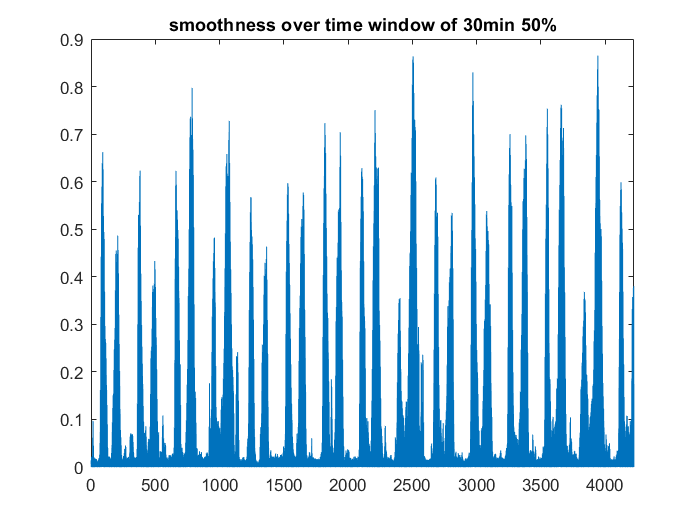

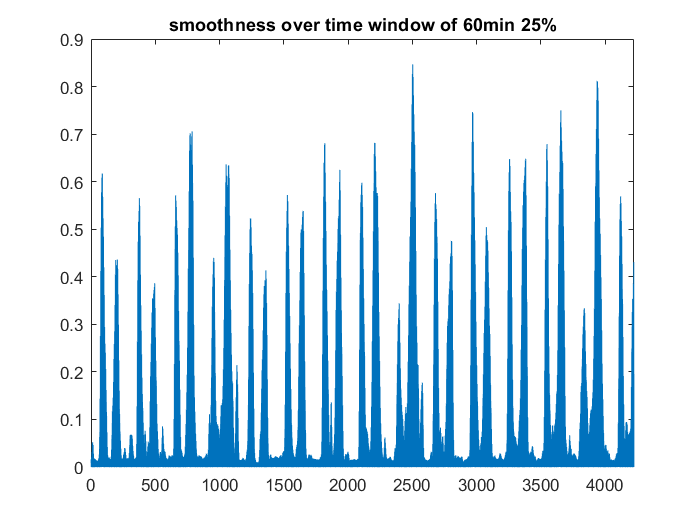

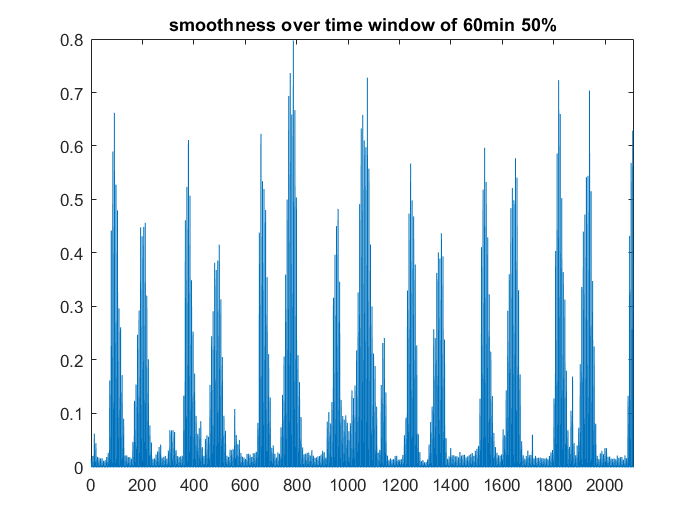


e_3_b

Smoothness of mentioned Graph signals are roughly similar.

Smoothness with time window 30min 25% overlap is good for detecting anamolies.

- How does overlap affect the smoothness? smoothness ossilates more with smaller time window.

- Small smoothness indicates that near neighborhoods of nodes are similar so overall smoothness becomes small.

## (f) Graph-Based Accident Analysis

clearvars -except X Lw W SpeedMat WeightMat 

X(1000:1012, 10:40) =0;

accident plots:


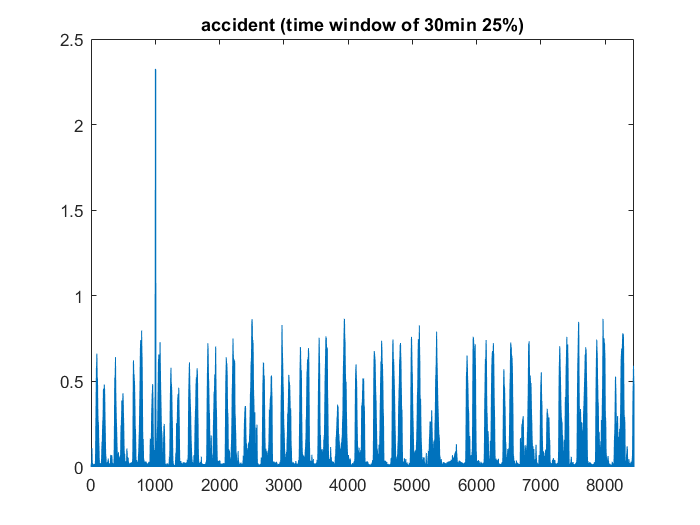

L6_25 = zeros(numel(X)/25/3,1);

for k=1:2:numel(X)/25/3
    x =mean(X(k:k+5, :));
    L6_25(k) =x * Lw * x';
end
figure
plot(L6_25);title('accident (time window of 30min 25%)');xlim([0,numel(L6_25)]);

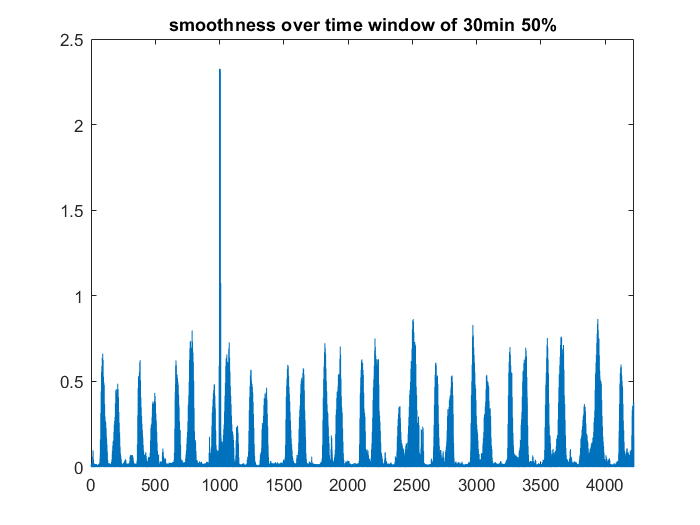

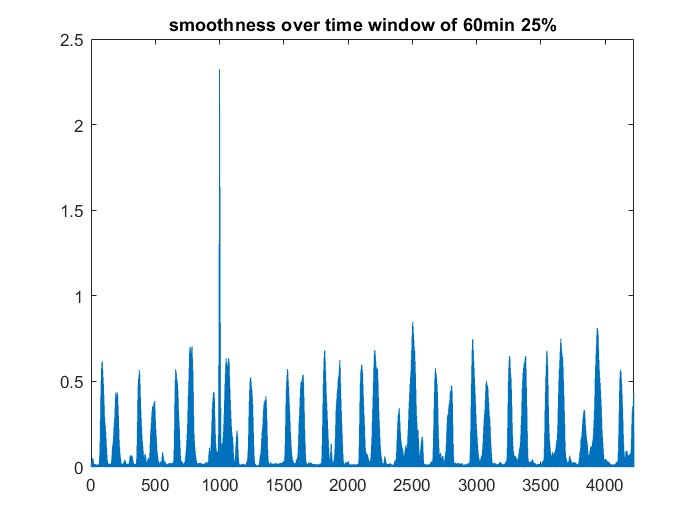

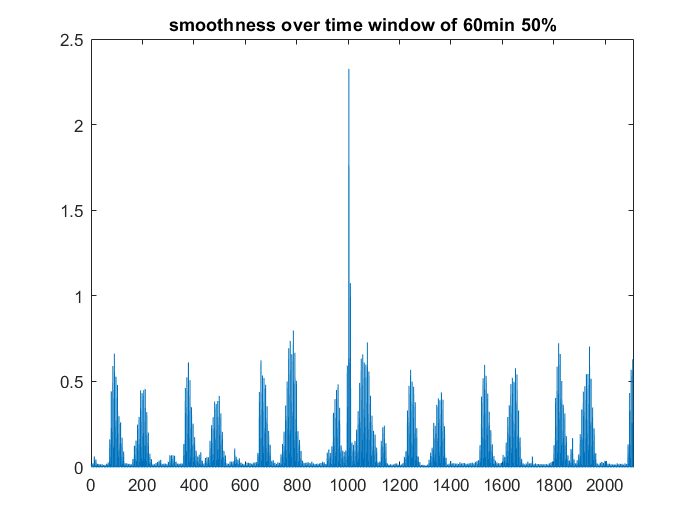


e_3_b

Graph smoothness increases after accident also time window of 60min 50% is suitibale to recognize accident of 60min interval.